# The WIM method for CICE6.

As CICE6 does not include wave propagation through ice, for wave forcing, we must attach a *waves-in-ice module* (WIM). This particular WIM has the following method:

- Take the signfiicant wave height, peak period and mean wave direction for the most northern ice-free cell.

- Apply a directional filter such that waves only propagate along longitudinal lines.

- Define the wave spectrum using a Bretschneider spectrum at this ice-free cell.

- Propagate through the ice (towards Antarctica) using the attenuation coefficent from Meylan et al. (2014).

- Calculate the signfiicant wave height and peak period for the propagated waves and feed this into CICE6.

% Preamble
clc
clear all
close all
addpath functions
%cd .. % Move up one directory
day = 9;
month = 1;
year = 2005;
sector = "SA";
if day < 9
    date = sprintf('%d-0%d-0%d', year, month, day);
else
    date = sprintf('%d-0%d-%d', year, month, day);
end
case_name = '31freq';
ticker = 1;
SIC = 0.15; 
filename = "/Volumes/NoahDay5TB/cases/31freq/history/iceh.2008-07-30.nc";%/Volumes/NoahDay5TB/cases/forcingnowaves/history/iceh.2005-07.nc";%"prra_input4MIPs_atmosphericState_OMIP_MRI-JRA55-do-1-5-0_gr_196201010130-196212312230.nc";
%strcat('cases/',case_name,"/history/iceh.",date,".nc");
% '/Users/noahday/Gadi/2010/JRA55_03hr_forcing_2010.nc';%'grid/gridded_ww3.glob_24m.200501.nc'; 
%filename = 'DATA/CESM/MONTHLY/ocean_forcing_clim_2D_gx1.20210330.nc';
% Read the header
%ncdisp(filename)
sector = "SH";
grid = 'gx1';
[lat,lon] = grid_read(grid);

%% Finding the ice edge
aice_data = data_format_sector(filename,"aice",sector);

[lat_ice_edge, lon_ice_edge,edge] = find_ice_edge(aice_data,SIC,sector,lat,lon);


% Plot areal ice concentration
 
conFigure(11,1)
f = figure;
[p,a] = map_plot(aice_data,"aice","SH");

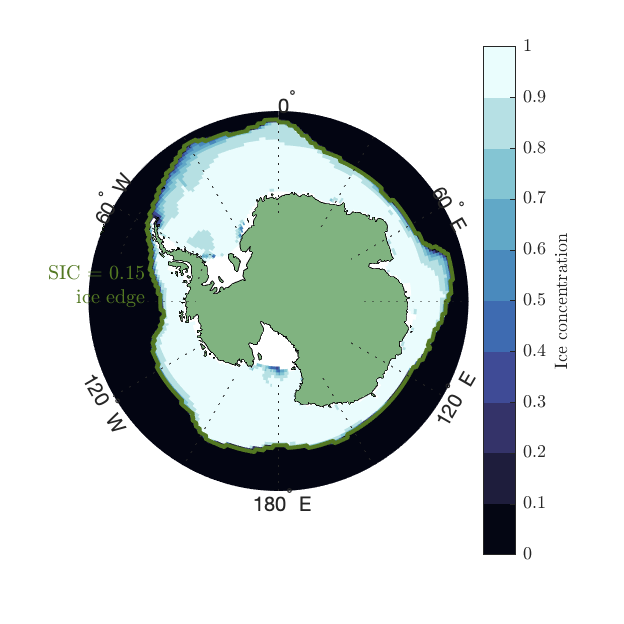

plotm(lat_ice_edge,lon_ice_edge,'-','color',0.7*[0.4660 0.6740 0.1880],'LineWidth',2) % Dark green
t = textm(lat_ice_edge(20)-5,lon_ice_edge(300),sprintf('SIC = %g\n ice edge',SIC),'HorizontalAlignment','right');
t.Color = 0.7*[0.4660 0.6740 0.1880];
%s = scaleruler
% setm(handlem('scaleruler'), ...
%     'XLoc',0.3, ... '
%     'YLoc',-0.52, ...
%     'TickDir','down', ...
%     'MajorTick',0:1000:1000, ...
%     'MinorTick',0:500:500, ...
%     'MajorTickLength',km2nm(150),...
%     'MinorTickLength',km2nm(150))

a.Label.String = "Ice concentration";
a.Label.Interpreter = "latex";
cmocean('ice',10)

%exportgraphics(f,'aice.pdf','ContentType','vector')


% Take the wave data from CAWCR for these cells
filename = "/Users/a1724548/GitHub/cice-dirs/input/CICE_data/forcing/gx1/CAWCR/MONTHLY/2005/ww3_200507.nc";
cawcr_filename = filename;
row = 37;
%ncdisp(filename)
lat = ncread(filename,"TLAT");
lon = ncread(filename,"TLON");
lat = rearrange_matrix(lat,row,2);
lon = rearrange_matrix(lon,row,2);
[m, ~] = size(lon);
lon = double([lon; lon(end,:) + 360/m]);
lat = double([lat; lat(end,:)]);
hour = 1;

dirdata = ncread(cawcr_filename,'dir');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
mwd_data = dir_out(:,:,1);

dirdata = ncread(cawcr_filename,'fp');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
fp_data = dir_out(:,:,1);

dirdata = ncread(cawcr_filename,'hs');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
hs_data = dir_out(:,:,1);


% Plot the wave stats

% Wave direction
mwd_vec = reshape(mwd_data,1,[]);
x_vec = reshape(cos(mwd_data),1,[]);
y_vec = reshape(sin(mwd_data),1,[]);
lat_vec = reshape(lat,1,[]);
lon_vec = reshape(lon,1,[]);
scale = 0.5;
pram.quiver_color = 'red';
% Signficant wave height
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),hs_data) 
    %quiverm(lat_vec,lon_vec,x_vec,y_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
     caxis([0,10])
    
 exportgraphics(f,'cawcr.pdf','ContentType','vector')

    
% Peak frequency
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),fp_data.^(-1))
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Peak period [s]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    
    

    
    
    
    
% SWH along ice edge
swh_ice_edge = zeros(size(lat)).*NaN;
for i = 1:length(edge)
    swh_ice_edge(i,edge(i)) = hs_data(i,edge(i));
    latedge_vec(i) = lat(i,edge(i));
    lonedge_vec(i) = lon(i,edge(i));
    xedge_vec(i) = cos(mwd_data(i,edge(i)));
    yedge_vec(i) = sin(mwd_data(i,edge(i)));
end
scale = 0.1;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_ice_edge) 
    quiverm(latedge_vec,lonedge_vec,xedge_vec,yedge_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
      caxis([0,10])
exportgraphics(f,'ice_edge.pdf','ContentType','vector')




% Directional filter
for i = 1:length(edge)
    if mwd_data(i,edge(i)) > pi/2 && mwd_data(i,edge(i)) < 3*pi/2
        xedgefilt_vec(i) = cos(pi);
        yedgefilt_vec(i) = sin(pi);
    else
        xedgefilt_vec(i) = 0;
        yedgefilt_vec(i) = 0;
    end
end
scale = 0.1;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_ice_edge) 
    quiverm(latedge_vec,lonedge_vec,xedgefilt_vec,yedgefilt_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([0,10])
    
exportgraphics(f,'ice_edge2.pdf','ContentType','vector')

    
    
% CICE output
filename = "/Volumes/NoahDay5TB/cases/31freq/history/iceh.2008-07-30.nc";

swh_data = data_format_sector(filename,"wave_sig_ht",sector);
ppd_data = data_format_sector(filename,"peak_period",sector);
mwd_data = data_format_sector(filename,"mean_wave_dir",sector);

idx = swh_data < eps;
swh_data(idx) = NaN;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_data) 
    %quiverm(latedge_vec,lonedge_vec,xedge_vec,yedge_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
 caxis([0,10])
        
 exportgraphics(f,'wave_prop_cice.pdf','ContentType','vector')

% Plot what the Bretschneider spectrum may look like




% Plot transect of attenuation




% Plot the map of the propagated waves through ice 